# Computational Physics (PHY4602) - Random Number and Simulation

## Overview

Simulation is an area of application where computers have come into their own. A simulation is a computer experiment which mirrors some aspect of the real world that appears to be based on random processes, or is too complicated to understand properly. Some examples are: radioactive decay, rolling dice, bacteria division and traffic flow. The essence of a simulation program is that the programmer is unable to predict beforehand exactly what the outcome of the program will be, which is true to the event being simulated.

## Random Number Generator

Random events are easily simulated in MATLAB with the function `rand`, which we have briefly encountered already. By default, `rand` returns a uniformly distributed pseudo-random number in the range $0\le x<1$. Note that a computer cannot generate truly random numbers, but they can be practically unpredictable.

The command `rand(1, 5)` returns a row vector of five random numbers:

RandomNumbers = rand(1, 5)

If you generate more random numbers during the same MATLAB session, you will get a different sequence each time, but each time you start a MATLAB session, the random number sequence begins at the same place. To produce a different sequence each time you start a session, `rand` can be initially seeded in a different way.

The call to the function `rng(Seed)` specifies the seed for the MATLAB random number generator. For example:

rng(42)
rand

 initializes the Mersenne Twister generator using a seed of 42.

There are various functions to generate random numbers, each produces different types of numbers:

RandNumbers = rand(1, 1000)                 % Returns uniformly distributed random numbers
RandnNumbers = randn(1, 1000)               % Returns normally distributed random numbers
RandiNumbers = randi([50, 150], 1, 1000)    % Returns uniformly distributed pseudorandom integers
RandpermNumbers = randperm(2000, 1000)      % Returns a row vector containing k (i.e., 1000) unique integers selected randomly from 1 to n (i.e., 2000)

Tiles = tiledlayout('flow', TileSpacing= 'tight', Padding = 'tight');
title(Tiles, 'Different types of random numbers');
nexttile;
plot(RandNumbers, 's')
title('Uniformly distributed random numbers')
nexttile;
plot(RandnNumbers, '^')
title('Normally distributed random numbers')
nexttile;
plot(RandiNumbers, 'o')
title('Uniformly distributed integers')
nexttile;
plot(RandpermNumbers, 'x')
title('Unique permutation of integers')

Between the four functions, only `randn` produces normally distributed random numbers, which can be visualized through a histogram:

histogram(RandnNumbers);
xlabel('Number'); ylabel('Occurence');
title('Normally distributed random number histogram')

### STEM Spotlight 💡: Traffic Flow Simulation

A major application of simulation is in modeling the traffic flow in large cities, in order to test different traffic light patterns before inflicting them on the real traffic. In this example we look at how to simulate the flow of a single line of traffic through one set of traffic lights. We make the following assumptions: 

- Traffic travels straight, without turning. 

- The probability of a car arriving at the lights in a particular second is independent of what happened during the previous second. This is called a Poisson process. This probability (call it $p$) may be estimated by watching cars at the intersection and monitoring their arrival pattern. In this simulation we take $p=0\ldotp 3$. 

- When the lights are green, assume the cars move through at a steady rate of, say, eight every ten seconds. 

- In the simulation, we will take the basic time period to be ten seconds, so we want a display showing the length of the queue of traffic (if any) at the lights every ten seconds.

- We will set the lights red or green for variable multiples of ten seconds.

The situation is modeled with a the following script which calls two functions: `go` and `stop`. In this example the lights are red for 40 seconds (red = 4) and green for 20 seconds (green = 2). The simulation runs for 50 seconds (n = 50).

NumCars = 0;
GreenTimer = 0;
RedTimer = 0; 
Light = "🔴";
NumSimulation = 50;
ProbThreshold = 0.3; % Probability of a car arriving
GreenPeriod = 3; % The period of the light is green
RedPeriod = 4; % The period of the light is red
for Index = 1 : NumSimulation 
    Prob = rand(1, 10); % 10 seconds means 10 random numbers
    NumCars = NumCars + sum(Prob < ProbThreshold);
    if Light == "🟢"
        [NumCars, Light, GreenTimer] = go(NumCars, Light, GreenTimer, GreenPeriod);
    else
        [Light, RedTimer] = stop(Light, RedTimer, RedPeriod);
    end
    if NumCars > 0
        Cars = join(repelem("🚗", NumCars));
    else
        Cars = " ";
    end
    fprintf('%4d  %s  %s\n', Index, Light, Cars);
end

## Monte Carlo Method

Monte Carlo methods are a broad class of computational algorithms that rely on repeated random sampling to obtain numerical results. One of the basic examples of getting started with the Monte Carlo algorithm is the estimation of $\pi$.

The idea is to simulate random $\left(x,y\right)$ points in a 2-D plane with domain as a square of side $2r$ units centered on $\left(0,0\right)$. Imagine a circle inside the same domain with same radius $r$ and inscribed into the square. We then calculate the ratio of number points that lied inside the circle and total number of generated points. Refer to the image below:

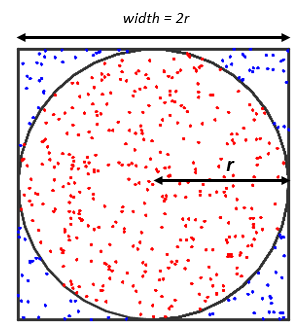

We know that area of the square is $4r^2$ while that of circle is $\pi r^2$.  The ratio of these two areas is $\pi r^2 /4r^2$. Now for a very large number of generated points:


$$\begin{array}{l}
\frac{\textrm{Number}\;\textrm{of}\;\textrm{points}\;\textrm{generated}\;\textrm{in}\;\textrm{the}\;\textrm{circle}}{\textrm{Total}\;\textrm{number}\;\textrm{of}\;\textrm{points}\;\textrm{generated}}=\frac{{\pi r}^2 }{4r^2 }=\frac{\pi }{4}\\
\pi =4\left(\frac{\textrm{Number}\;\textrm{of}\;\textrm{points}\;\textrm{generated}\;\textrm{in}\;\textrm{the}\;\textrm{circle}}{\textrm{Total}\;\textrm{number}\;\textrm{of}\;\textrm{points}\;\textrm{generated}}\right)
\end{array}$$


The beauty of this algorithm is that we don’t need any [graphics or simulation](https://youtube.com/shorts/Tov4W3QL9Js?feature=share) to display the generated points. We simply generate random $\left(x,y\right)$ pairs and then check if $x^2 +y^2 \le 1$. If yes, we increment the number of points that appears inside the circle. In randomized and simulation algorithms like Monte Carlo, the more the number of iterations, the more accurate the result is. The following script estimates the value of $\pi$:

NumSimulation = 20000;
NumCirclePoints = 0;
EstimatedPi = NaN(1, NumSimulation);
for i = 1 : NumSimulation
    X = -1 + 2*rand; % rand generates a number between [0, 1]. Hence, the normalization to get a number between [-1, 1]
    Y = -1 + 2*rand;
    Distance = X ^ 2 + Y ^ 2;
    if Distance <= 1
        NumCirclePoints = NumCirclePoints + 1;
    end
    NumSquarePoints = i;
    EstimatedPi(i) = 4 * (NumCirclePoints / NumSquarePoints);
    if ~rem(i, NumSimulation / 100) % Only display the current estimation every 100 iterations
        fprintf('Current estimation of : %.8f\n', EstimatedPi(i));
    end
end    
delete(gca);
hold on
yline(pi, 'r', 'True value of π');
plot(EstimatedPi);
hold off
xlabel('Iteration'), ylabel('Estimated value of π');
fprintf('Final estimation of π: %.8f', EstimatedPi(end));

### Physics Pinpoint 🔎: The Ising Model

The Ising model displays many of the thermodynamic properties of magnetic materials. Imagine a chunk of material being made up of a large number of regularly spaced microscopic magnets. In this simple model each microscopic magnet can only point up or down. The quantum mechanical property of electrons called "spin" also has this two-valuedness, so we'll refer to these simple magnets as spins from here on. The total energy of the material depends on the relationship between neighboring spins. In ferromagnets, spins tend to align with their neighbors, so in our model, the energy must be lower when neighboring spins align than when they don't. 

The spins can have the value $+1$ or $-1$, and $J$ is a physical constant. We initialize a square matrix that has `DimensionSize` spins in each dimension; an average of half (`ProbSpinUp = 0.5`) spins initially in the +1 state; and we'll set `JConst` to have value 1 for simplicity:

We can efficiently calculate the sum of neighbors for all spins at once by summing shifted copies of `Spins`. The shifts in each direction can be made with the function `circshift` as follows:

Each spin $\sigma_m$ contributes an energy $E_m$ to the total energy, where


$$E_m = - J \sigma_m \sum_n \sigma_n \,,$$


and $\sigma_n$ are nearest neighboring spins to $\sigma_m$. Therefore, each spin can be multiplied by its corresponding sum of neighbors:

The total energy for a ferromagnet without an external magnetic field can be written as:


$$E = - J \frac{1}{2}\sum_{m,\,n} \sigma_m \sigma_n=\frac{1}{2}\sum_{m}E_m\ ,$$


Recall that the factor of one-half accounts for the double counting of the energy between $(m,n)$ and $(n,m)$. 

The mean energy per spin, $\langle E\rangle$, is useful to compare simulations with different numbers of spins in the matrix,

The magnetization $M$ of a material is defined as the net magnetic moment per unit volume. If we choose to have one atom per unit volume, then the mean magnetization, $\langle M \rangle$ or `Mmean`, can be written as the average spin moment:


$$\langle M \rangle = \frac{1}{N} \sum_{m}^{N} \sigma_m \, .$$


where $N$ is the total number of spins in the ferromagnet.

Statistical mechanics tells us that the probability that the spins are in one configuration or another is proportional to $e^{-(\textrm{Energy of state}) / kT},$ where $k$ is the Boltzmann constant and $T$ is the temperature. If a single spin $\sigma_m$ was to flip orientation, the total energy would change by an amount:


$$\Delta E = E_{\textrm{final}} - E_{\textrm{initial}} = \left(-J(-\sigma_m)\sum_n \sigma_n\right) - \left( -J\sigma_m\sum_n \sigma_n \right) = 2 J \sigma_m \sum_n  \sigma_n\,,$$


where $\sigma_n$ are the nearest neighbors to $\sigma_m$. The probabilities of these two states that differ by a single spin flip are proportional to


$$e^{-\Delta E / kT}.$$


The dynamics of the collection of spins can be modeled by:

- Randomly selecting a spin, 

- Calculating the change in total energy $\Delta E$ that would be caused by flipping it, 

- If $\Delta E < 0$, then flip the spin; otherwise flip the spin with probability $e^{-\Delta E / kT}$,

- Repeat.

This procedure is called the Metropolis algorithm that can be executed by the following script:

 
kT = 10; % Boltzmann constant x Temperature
JConst  = 1;

% Initialization
DimensionSize = 2^7;
ProbSpinUp = 0.5;
Spins = sign(ProbSpinUp - rand(DimensionSize));
NumIterations = 2^8;

% Metropolis algorithm
for i = 1 : NumIterations
    for s = 1 : DimensionSize^2
        LinearIndex = randi(numel(Spins));  % Pick a random spin
        [Row, Col]  = ind2sub(size(Spins), LinearIndex);

        % Find its nearest neighbors
        Above = mod(Row - 1 - 1, size(Spins,1)) + 1;
        Below = mod(Row + 1 - 1, size(Spins,1)) + 1;
        Left  = mod(Col - 1 - 1, size(Spins,2)) + 1;
        Right = mod(Col + 1 - 1, size(Spins,2)) + 1;
        Neighbors = [Spins(Above, Col); Spins(Row, Left); Spins(Row, Right); Spins(Below, Col)];

        % Calculate energy change if this spin is flipped
        EnergyChange = 2 * JConst * Spins(Row, Col) * sum(Neighbors);

        % Boltzmann probability of flipping
        FlipProb = exp(-EnergyChange / kT);

        % Spin flip condition
        if EnergyChange <= 0 || rand <= FlipProb
            Spins(Row, Col) = - Spins(Row, Col);
        end
    end
    imagesc(Spins);
    axis equal off;
    drawnow;
end
% The mean energy
SumOfNeighbors = circshift(Spins, [0, 1]) ...
    + circshift(Spins, [0, -1]) ...
    + circshift(Spins, [1, 0]) ...
    + circshift(Spins, [-1, 0]);
SpinEnergy = - JConst * Spins .* SumOfNeighbors;
TotalEnergy  = 0.5 * sum(SpinEnergy, 'all')
MeanEnergy = TotalEnergy / numel(Spins)
MeanMagnetization = mean(Spins(:))

**Local Functions**

function [NumCars, Light, GreenTimer] = go(NumCars, Light, GreenTimer, GreenPeriod)
GreenTimer = GreenTimer + 1;
NumCars = NumCars - 8; % Let 8 cars through
if NumCars < 0
    NumCars = 0;
end
if GreenTimer == GreenPeriod % Check if lights need to change
    Light = "🔴";
    GreenTimer = 0;
end
end

function [Light, RedTimer] = stop(Light, RedTimer, RedPeriod)
RedTimer = RedTimer + 1; % The period of light is red
if RedTimer == RedPeriod % Check if lights must be changed
    Light = "🟢";
    RedTimer = 0;
end
end